# Record and Playback Blocks

[ ](https://matlab.mathworks.com/open/github/v1?repo=simulink/blog&project=2025_06_10_RecordPlayback/RecordPlayback.prj)

Today I want to talk about two relatively new blocks: [Record](https://www.mathworks.com/help/simulink/slref/record.html) and [Playback](https://www.mathworks.com/help/simulink/slref/playback.html).

## Record Block

Let's start with this simple example where I connect two signals to the Record block:

mdl = 'MassSpringDamper';
open_system(mdl);

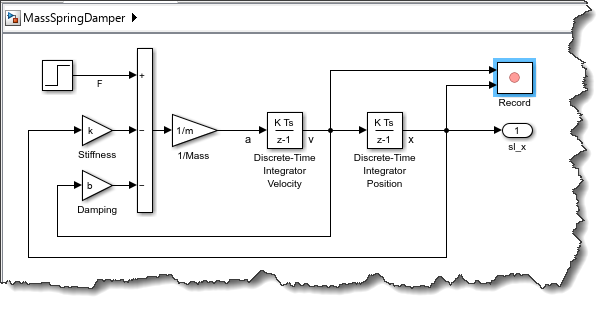

When you double-click on the block, the first thing you will notice is that the Record block gives you the possibility to visualize the signals connected to it with a look and feel similar to the [Simulation Data Inspector](https://www.mathworks.com/help/simulink/slref/simulationdatainspector.html), but embedded in the Simulink canvas.

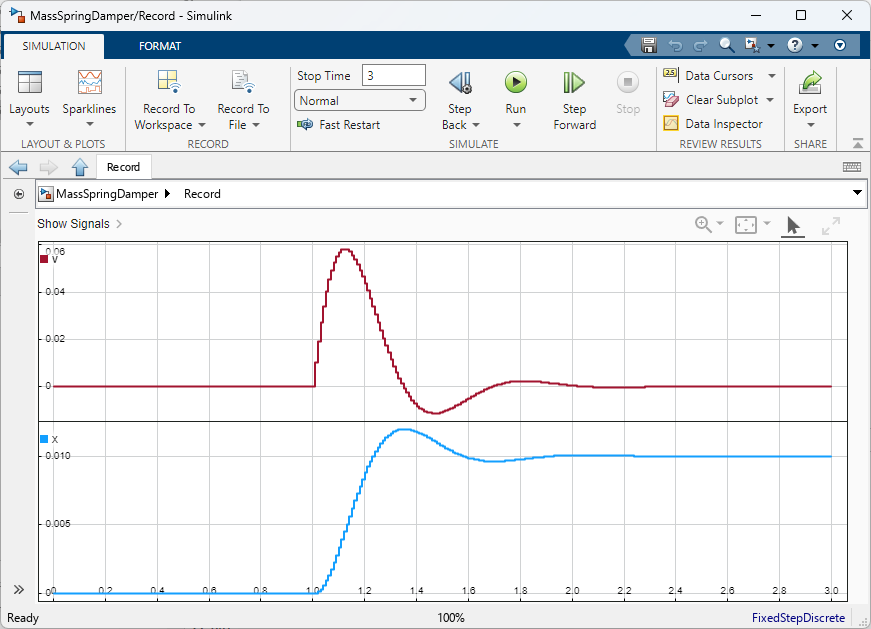

Like the Simulation Data Inspector, the layout can be configured to display the signals in many different ways. Here I added an XY plot in addition to the time plots.

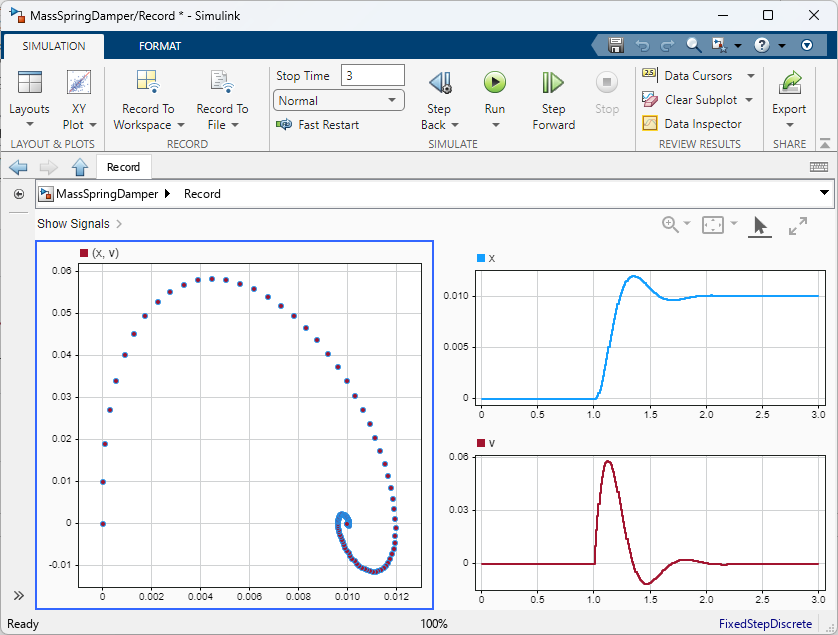

Like the [To File](https://www.mathworks.com/help/simulink/slref/tofile.html) and [To Workspace](https://www.mathworks.com/help/simulink/slref/toworkspace.html) blocks, the Record block can also save the signals. When saving to workspace, the data will be included in the SimulationOutput object like all other logged data: 

in = Simulink.SimulationInput(mdl);
in = in.setBlockParameter('MassSpringDamper/Record',"RecordToWorkspace","on");
in = in.setBlockParameter('MassSpringDamper/Record',"VariableName","RecordedData");
out = sim(in);
out.RecordedData

ans = Simulink.SimulationData.Dataset 'Run 43: MassSpringDamper' with 2 elements

                         Name  PropagatedName  BlockPath               
                         ____  ______________  _______________________ 
    1  [1x1 Signal]      v     v               MassSpringDamper/Record
    2  [1x1 Signal]      x     x               MassSpringDamper/Record

  - Use braces { } to access, modify, or add elements using index.


When recording to file, you have multiple options for the file format, including Excel and Parquet.

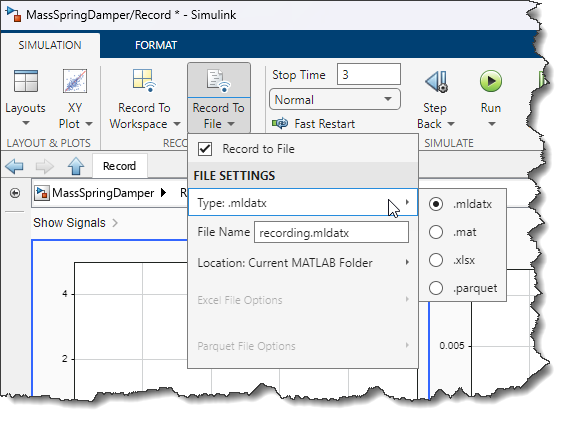

See this example to learn more about the option to record to a [Parquet file](https://en.wikipedia.org/wiki/Apache_Parquet): [Export Data to Parquet File Using Record Block](https://www.mathworks.com/help/releases/R2025a/simulink/ug/export-data-to-parquet-file-using-record-block.html)

## Playback

Working in technical support, one thing I often need to do is simplify and isolate issues. For that, it can be very useful to log signals, open loops and replay recorded signals. For the above model, I can reply the recorded data using this model:

open_system('MassSpringDamperCut')

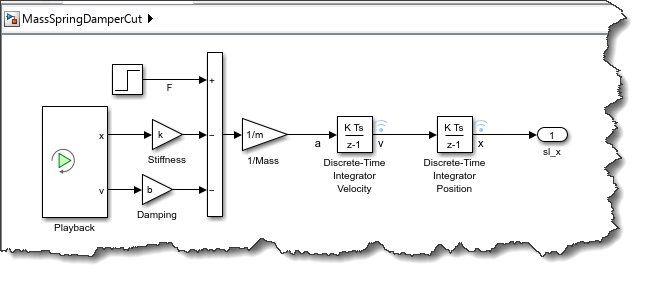

When adding a Playback block to a model, it offers you to choose signals from the MATLAB workspace and/or from a file. If you choose a file, it supports all the formats supported by the Record block and even allows you to create a customer file reader if needed.

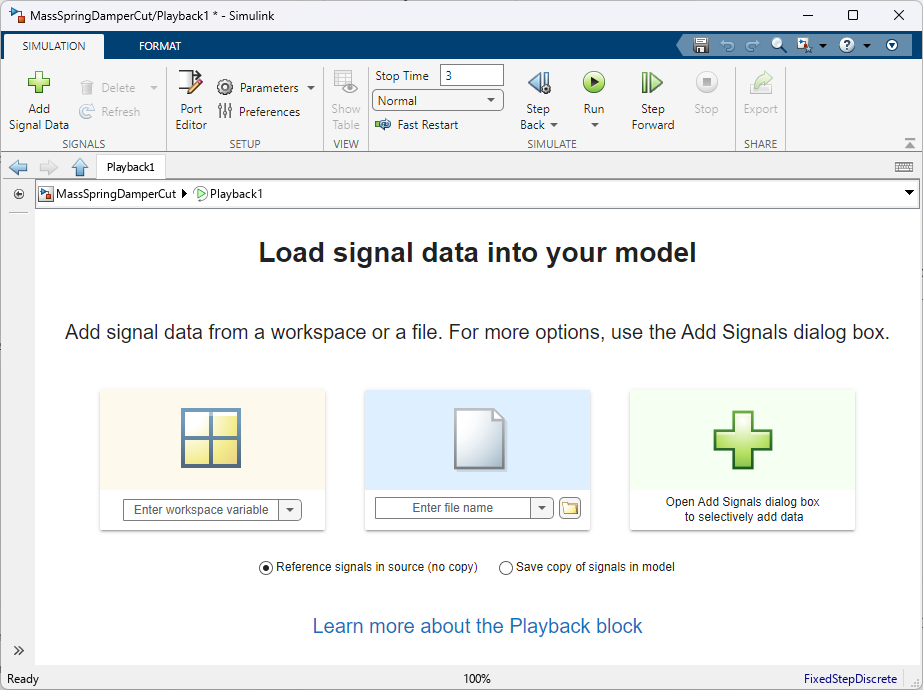

If you want, you can even combine data from multiple sources, here is an example where I have signals from a MAT-file, and from the base workspace. I also like the possibility to view the signals as a table in addition to the plot.

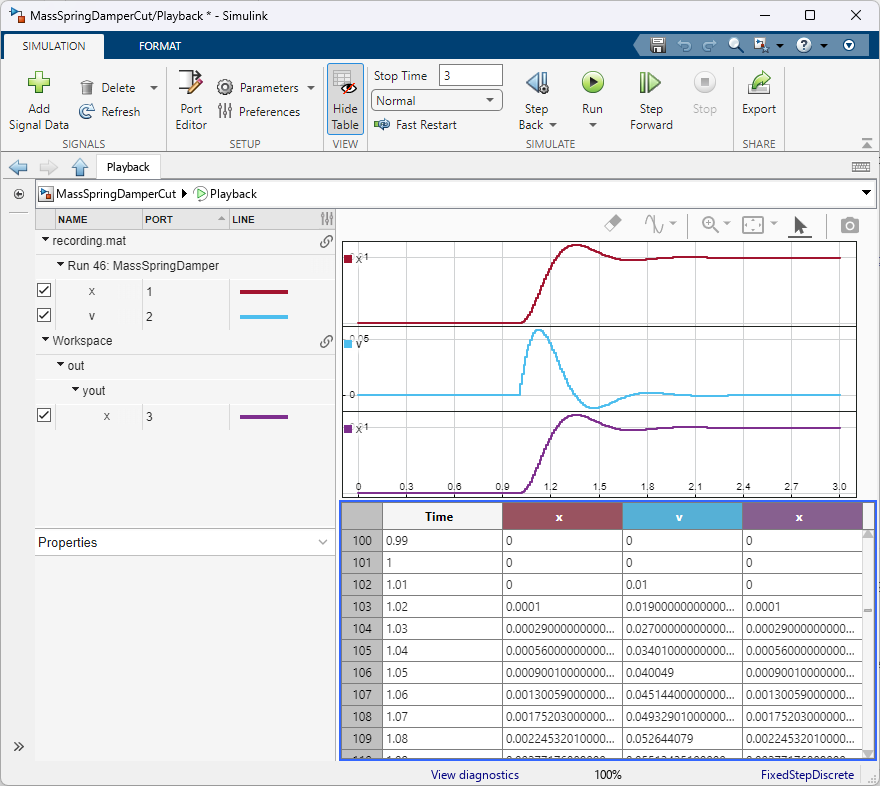

## Playback signals from the Simulation Data Inspector

In addition to loading signals from the base workspace or a file, the Playback block can directly import signals from runs in the Simulation Data Inspector. In that case, the data will be copied and saved with the model, so you can delete the data from the Simulation Data Inspector once you don't need it there anymore.

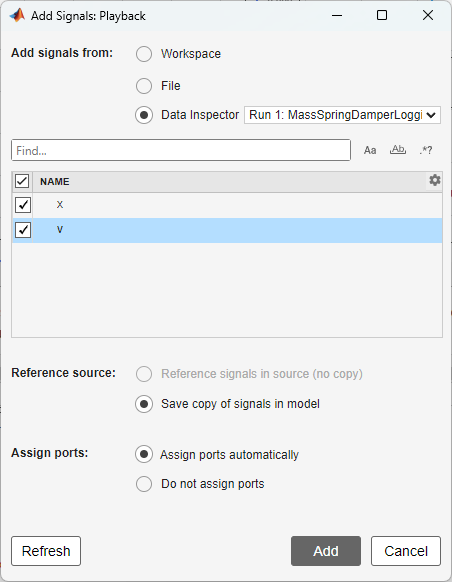

## Now it's your turn

Give the Record and Playback blocks a try and let us know what you think in the comments below.